# A really basic Kalman Filter

As with many algorithms used in modern Controls design, a Kalman Filter requires a model of the system. The modeling process also helps to illuminate some key concepts in Kalman Filtering.

## A simple model of some basic characteristics of the problem

We'll focus on modeling just one key characteristic of the problem: the reticle sensor measurement is received 1 sample later than the vessel sensor measurements (for simplicity, we start with a single vessel sensor measurement). 

As a toy example to gain insight into the modeling process, imagine that the EUV is just the previous value of EUV plus a random number. What do the measurements look like? If we write a for-loop to represent this time series, it would look like...

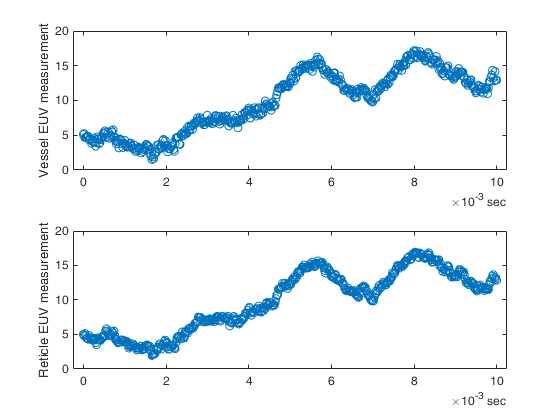

Ts = 20e-6; % sample time
Time = seconds(0:Ts:0.01); % simulate for 10 milliseconds

% parametrization of system
deuvstd = 0.3;

internalSensorErrorStd = 0.3;

% initial state of the system:
previous_EUV = 0; %#ok<NASGU> this actually doesn't matter.
current_EUV = 5;

H.EUV_actual   = zeros(size(Time)); % EUV that actually reached reticle in sample k
H.EUV_internal = zeros(size(Time)); % measurement of internal sensor in sample k
H.EUV_external = zeros(size(Time)); % measurement of reticle sensor in sample k (delayed)

% seed the random number generator so the simulation always runs the same
% way
rng(42)
for k = 1:length(Time)
  %%% Plant %%%
  previous_EUV = current_EUV;
  current_EUV = previous_EUV+deuvstd*randn; % this is actually not a good model...
  % ...as you'll see when we plot the results of the simulation
  
  % store the history of the signal:
  H.EUV_actual(k) = current_EUV;
  
  %% Sensors %%
  % the reticle sensor measurement contains the previous EUV  
  H.EUV_external(k) = previous_EUV;
  
  % the sensor on the source measures the current EUV, but with some error
  % in lieu of a better model for the error, we will treat it as an i.i.d.
  % normally distributed r.v.
  H.EUV_internal(k) = current_EUV + internalSensorErrorStd*randn;
end

figure
h(1) = subplot(2,1,1);
plot(Time,H.EUV_internal,'o:');ylabel("Vessel EUV measurement")
h(2) = subplot(2,1,2);
plot(Time,H.EUV_external,'o:');ylabel("Reticle EUV measurement")
linkaxes(h,'x')

Obvious statement: In order to run the simulation, we needed to keep track of two key values at each iteration: the previous_EUV and the current_EUV.

These two values are the *state* of the system at a given time. At any given time (any given iteration of the for-loop), you need the full state information to progress to the next point in time / iteration.

Obvious statement: A property of the state is that it encodes all the information from the past which is relevant for determining the future. In other words, at any iteration k, if you know the state at iteration k, then whatever happened on iterations 1 through k-1 do not matter for determining future iterations k+1, k+2, ...

 This concept of state is fundamental; just as the simulation requires the full state information to iterate, we will see that the Kalman Filter must likewise represent the full state estimate in its algorithm. And! Just as the state of the simulation at a given moment in time is sufficient to run the simulation from that point in time, the Kalman Filter likewise only needs to keep track of the state estimate as opposed to the full history of measurements up to the present time.

Given the state, there is a compact, matrix expression for each iteration of the for loop:


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
{\textrm{EUV}}_{k+1} \\
{\textrm{EUVdelayed}}_{k+1} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
1 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\textrm{EUV}}_k \\
{\textrm{EUVdelayed}}_k 
\end{array}\right\rbrack \left(+B\;u_k \right)+\left\lbrack \begin{array}{c}
{\textrm{dEUV}}_k \\
0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
{\textrm{EUV}\_\textrm{internal}}_k \\
\textrm{EUV}\_{\textrm{external}}_k 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\textrm{EUV}}_k \\
{\textrm{EUVdelayed}}_k 
\end{array}\right\rbrack \;\left(+D\;u_k \right)+\left\lbrack \begin{array}{c}
\textrm{internalSensorError}\\
0
\end{array}\right\rbrack 
\end{array}$$


So let


$$x_k \doteq$$

$$\left\lbrack \begin{array}{c}
{\textrm{EUV}}_k \\
{\textrm{EUVdelayed}}_k 
\end{array}\right\rbrack ,w_k =\left\lbrack \begin{array}{c}
{\textrm{dEUV}}_k \\
0
\end{array}\right\rbrack ,\textrm{and}\;v_k =\left\lbrack \begin{array}{c}
\textrm{internalSensorError}\\
0
\end{array}\right\rbrack \;$$


... and that's how we arrive at the usual state space equation:


$$\begin{array}{l}
x_{k+1} =A\;x_k +B\;u_k +w_k \\
y_k =C\;x_k +D\;u_k +v_k 
\end{array}$$
 

As a totally unnecessary sanity check, we can rewrite the for-loop with these matrix expressions:

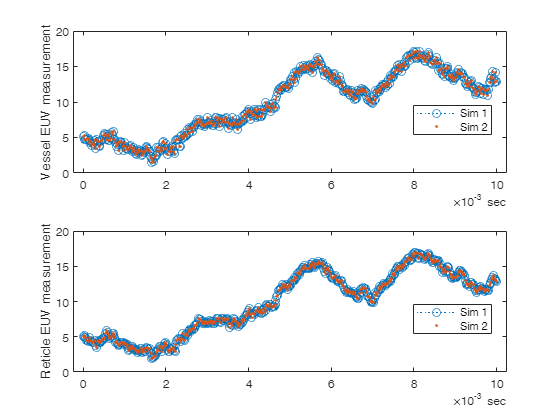

% initial state of the system:
previous_EUV = 0;
current_EUV = 5;

xk = [current_EUV;
  previous_EUV];
A = [1,0;1,0];
B = [0;0];
uk = 0; % we'll include the exogenous input for completeness even though it's uniformly zero
C = [1,0;0,1];
D = [0;0];


H1.EUV_actual   = zeros(size(Time)); % EUV that actually reached reticle in sample k
H1.EUV_internal = zeros(size(Time)); % measurement of internal sensor in sample k
H1.EUV_external = zeros(size(Time)); % measurement of reticle sensor in sample k (delayed)

% seed the random number generator so the simulation always runs the same
% way
rng(42)
for k = 1:length(Time)
  % Replace this...
  %   previous_EUV = current_EUV;
  %   current_EUV = previous_EUV+deuvstd*randn;
  %   H.EUV_actual = current_EUV;
  %   H.EUV_external(k) = previous_EUV;
  % With this...
  wk = [deuvstd*randn;
    0];
  xk = A*xk + B*uk + wk;
  H1.EUV_actual(k) = xk(1);
  
  % Replace this...
  %   H.EUV_external(k) = previous_EUV;
  %   H.EUV_internal(k) = current_EUV + internalSensorErrorStd*randn;
  % With this...
  vk = [internalSensorErrorStd*randn;
    0];
  yk = C*xk + D*uk + vk;
  
  H1.EUV_external(k) = yk(2);
  H1.EUV_internal(k) = yk(1);
  
end

h(1) = subplot(2,1,1);
hold on
plot(Time,H1.EUV_internal,'.');
legend("Sim 1","Sim 2",'location','best')
h(2) = subplot(2,1,2);
hold on
plot(Time,H1.EUV_external,'.');
legend("Sim 1","Sim 2",'location','best')

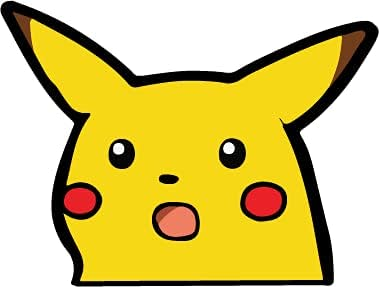

(No one was surprised.)

## Finally, the Kalman Filter

### So... what's a Kalman Filter?

Given a state space model, a Kalman Filter calculates the expected value of the state using information from the history of measurements, as well as the (imperfect) knowledge of the initial condition, i.e., $E\left\lbrack x_k \left|y_k ,y_{k-1} ,\ldotp \ldotp \ldotp ,y_0 \right.\right\rbrack$. This estimate has some neat properties;

- One can prove that this estimate is optimal in some sense (relation between conditional expectation and projections).

- The Kalman Filter is a Bayesian estimator for a class of hidden Markov models.

You'll need to take an actual optimal estimation course, or read [Optimal Filtering](https://www.amazon.com/Optimal-Filtering-Engineering-Anderson-Paperback/dp/B007S6GQN4), to learn more.

The conditional expectation can be hard to wrap your head around, and its derivation does not provide any easy visualization. Consider a toy example:

$y=x+v$,

where x is normally distributed with mean 0 and standard deviation $\sigma_x$ and v is normally distributed with mean 0 and standard deviation $\sigma_v$. This is typically denoted as $x~N\left(0,\sigma_x^2 \right)$and $v~N\left(0,\sigma_v^2 \right)$.

Also, assume $x$ and $v$ are independent, $x\bot v$

Solve for $E\left\lbrack x\left|y=1\right.\right\rbrack$.

- Disclaimer: As usual, I'm not going to prove anything about the method I use below; importantly, one should try to prove convergence formally, since that tells you whether an approximation is even sensible. However, in the interest of time, and also because the method below is not a standard way to teach Kalman Filtering, I won't try.

Thanks to modern computing, we can brute-force approximate this by repeatedly simulating different x and v values and then looking at only combinations that sum up to approximately 1 (don't run this on an underpowered processor or with insufficient RAM).

switch "yes"
  case "yes"
    nnn = 1e5;
  case "potato"
    nnn = 1e4;
end

% Drag the slider around to change the standard deviations of x and v:
sx = 10^1; % standard deviation of x
sv = 1 / sx; % use an inverse relation for standard deviation of v for numerical reasons

disp("Standard deviation of x = "+sx)

Standard deviation of x = 10


disp("Standard deviation of v = "+sv)

Standard deviation of v = 0.1


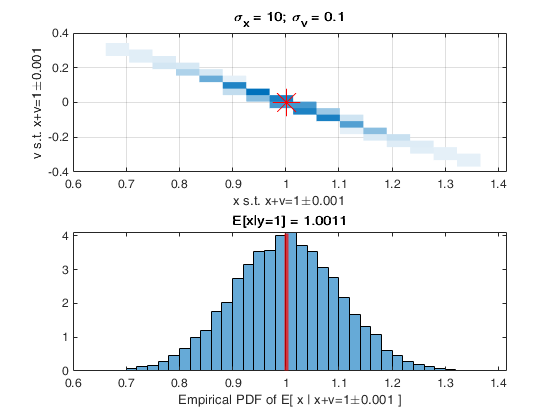


z = 1;
tol = 1e-3; % x + v = 1 +/- tol

% Simulate a whole bunch of X and V values:
X = sx*randn(nnn/tol,1); 
V = sv*randn(nnn/tol,1);

% Only take values which are close enough to 1
idx = abs(X + V - z) < tol;

figure
% Do a heat map of x and v combinations which sum up to 1. A dark colored
% bin indicates a larger number of x and v combinations
h(1) = subplot(2,1,1);
binscatter(X(idx),V(idx))
hold on
plot(mean(X(idx)),mean(V(idx)),'*r','markersize',20)
title("\sigma_x = "+sx+"; \sigma_v = "+sv)
xlabel("x s.t. x+v=1\pm"+tol)
ylabel("v s.t. x+v=1\pm"+tol)
grid on
colorbar('off')

h(2) = subplot(2,1,2);
histogram(X(idx),'Normalization',"pdf")
hold on
xline(mean(X(idx)),'r',"LineWidth",3)
title("E[x|y="+z+"] = "+mean(X(idx)))
xlabel("Empirical PDF of E[ x | x+v=1\pm"+tol+" ]")
linkaxes(h,'x')

As you change the ratio of standard deviations of x and v, note the following:

- When $\sigma_x$ is small and $\sigma_v$ is relatively larger, $E\left\lbrack x\left|y=1\right.\right\rbrack \approx 0$. This makes sense because a small $\sigma_x$ means we were already quite sure that $x=0$; therefore, $y=1$ is most likely due to variation in $v$

- When $\sigma_x$ is large and $\sigma_v$ is relatively smaller, $E\left\lbrack x\left|y=1\right.\right\rbrack \approx 1$. The reasoning is the same as case #1, mutatis mutandis.

- When $\sigma_x =\sigma_v$, $E\left\lbrack x\left|y=1\right.\right\rbrack =0\ldotp 5$. Both $x$ and $v$ are zero mean with the same variance, so we expect each to contribute half to the sum $x+v=1$ (on average).

Loosely speaking, $E\left\lbrack x\left|y=1\right.\right\rbrack$ is attributing some amount of the sum $x+v=1$ to $x$ and the rest to $v$ based on the ratio of their variations. The actual formula is


$$E\left\lbrack x\left|y=z\right.\right\rbrack =\frac{\sigma_x^2 }{\sigma_x^2 +\sigma_v^2 }z$$


See [https://math.stackexchange.com/questions/1368922/conditional-expectation-on-gaussian-random-variables](https://math.stackexchange.com/questions/1368922/conditional-expectation-on-gaussian-random-variables) for a clever derivation.

Some other noteworthy properties:

- Note that $E\left\lbrack x\left|y=1\right.\right\rbrack$ has some variation in its histogram -- it is, itself, a random variable. (Compare, for example, to $E\left\lbrack x\right\rbrack$, which is not random.)

- $E\left\lbrack x\left|y=1\right.\right\rbrack$ is normally distributed. This is one of many seemingly magical properties of the normal distribution.

- The standard deviation of $E\left\lbrack x\left|y=1\right.\right\rbrack$ is (with some uncertainty, because we're doing things computationally) never greater than the original standard deviation of x, $\sigma_x$. In other words, measurement never makes your knowledge of the state more uncertain (within this mathematical formulation).

This is the heart of Kalman Filtering.

(It's worth taking a step back and marveling that mathematicians were able to prove these properties way back before computers were a thing -- a strong argument for why we go through the academic exercise of mathematical proofs.)

### Finally, (finally) the Kalman Filter

We know that solving for $E\left\lbrack x\left|y\right.\right\rbrack$ requires carrying around the variances of $x$ and $v$. I will say without proof that, if we want to do this recursively, and we furthermore want to use the state to represent the past, then we need to additionally carry around some sort of measure of the variance of $E\left\lbrack x\left|y\right.\right\rbrack$ (we actually need to keep track of its error covariance -- again, take a real class).

For notational brevity, let us write...


$$\begin{array}{l}
x_{k\left|k\right.} \doteq E\left\lbrack x_k \left|y_k ,y_{k-1} ,\ldotp \ldotp \ldotp ,y_0 \right.\right\rbrack \\
x_{k+1\left|k\right.} \doteq E\left\lbrack x_{k+1} \left|y_k ,y_{k-1} ,\ldotp \ldotp \ldotp ,y_0 \right.\right\rbrack \\
\Sigma_{k\left|k\right.} \doteq E\left\lbrack \left(\left(x_k -x_{k\left|k\right.} \right){\left(x_k -x_{k\left|k\right.} \right)}^T \right)\left|y_k ,y_{k-1} ,\ldotp \ldotp \ldotp ,y_0 \right.\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\gets \textrm{Error}\;\textrm{covariance}\\
\Sigma_{k+1\left|k\right.} \doteq E\left\lbrack \left(\left(x_{k+1} -x_{k+1\left|k\right.} \right){\left(x_{k+1} -x_{k+1\left|k\right.} \right)}^T \right)\left|y_k ,y_{k-1} ,\ldotp \ldotp \ldotp ,y_0 \right.\right\rbrack \;\;\gets \textrm{Error}\;\textrm{covariance}
\end{array}$$


Then the Kalman Filter equations for...


$$\begin{array}{l}
x_{k+1} =A\;x_k +w_k \\
y_k =C\;x_k +v_k 
\end{array}$$
 

with $x_0 \doteq x_{0\left|-1\right.} ~N\left(\bar{x_0 } ,\Sigma_0 \right)$, $w_k ~N\left(0,Q_k \right)$, $v_k ~N\left(0,R_k \right)$, and $w_k \bot v_j \bot x_0 \forall \;k,j$

are...


$$\begin{array}{l}
x_{k\left|k\right.} =x_{k\left|k-1\right.} +\Sigma_{k\left|k-1\right.} C^T {\left(C\Sigma_{k\left|k-1\right.} C^T +R_k \right)}^{-1} \left(y_k -Cx_{k\left|k-1\right.} \right)\\
x_{k+1\left|k\right.} =Ax_{k\left|k\right.} \\
\Sigma_{k\left|k\right.} =\Sigma_{k\left|k-1\right.} -\Sigma_{k\left|k-1\right.} C^T {\left(C\Sigma_{k\left|k-1\right.} C^T +R_k \right)}^{-1} {C\Sigma }_{k\left|k-1\right.} \\
\Sigma_{k+1\left|k\right.} =A\Sigma_{k\left|k\right.} A^T +Q_k 
\end{array}$$


Note that I've thrown out the input, $u_k$, to save some writing. When $u_k$ is deterministically known, as it should be because a controller would always know what value it commanded, then $u_k$ does not introduce randomness, and so it can be superimposed directly on the state estimate equations, and it does not affect the covariance update equations. On the other hand, when $u_k$ is the output of a linear feedback controller, then it can be written as a function of the state.

Okay, time to add the filter to the simulation:

% same stuff from before
previous_EUV = 0;
current_EUV = 5;

xk = [current_EUV;
  previous_EUV];
A = [1,0;1,0];
B = [0;0];
uk = 0; % we'll include the exogenous input for completeness even though it's uniformly zero
C = [1,0;0,1];
D = [0;0];

% Kalman Filter stuff:
  % Define the initial condition for the state estimate.
  % In general, the guess of the initial condition is wrong:
  xkEstimate = [0;0]; % we'll use some obviously incorrect values here
  
  % We also need to parametrize our uncertainty of the initial condition of
  % the state. When in doubt, use a large value for this.
  Sk = eye(2)*5;
  % ... and the variances of wk and vk:
  Qk = [deuvstd^2,0;0,0];
  % pro-tip: if you have non-linearities and are unsure how to model them, a
  % quick and dirty fix is to use a larger Qk matrix to represent that
  % uncertainty.
  Rk = [internalSensorErrorStd^2,0;0,0];
  % pro-tip: if your Kalman Filter is unstable (because, for instance, your
  % model is unobservable, which you should avoid, by the way), you can add a
  % small delta to Rk so that it is strictly positive definite. Ask a
  % professor.

Hf.EUV_actual   = zeros(size(Time)); % EUV that actually reached reticle in sample k
Hf.EUV_internal = zeros(size(Time)); % measurement of internal sensor in sample k
Hf.EUV_external = zeros(size(Time)); % measurement of reticle sensor in sample k (delayed)
Hf.EUV_estimate = zeros(size(Time)); % this will be the KF estimate of EUV_actual

% seed the random number generator so the simulation always runs the same
% way
rng(42)
for k = 1:length(Time)

  % The plant
  wk = [deuvstd*randn;
    0];
  xk = A*xk + wk;
  Hf.EUV_actual(k) = xk(1);
  
  % The sensor
  vk = [internalSensorErrorStd*randn;
    0];
  yk = C*xk + vk;
  Hf.EUV_external(k) = yk(2);
  Hf.EUV_internal(k) = yk(1);
  
  % The Kalman Filter  

- 
$$\begin{array}{l}
x_{k\left|k\right.} =x_{k\left|k-1\right.} +\Sigma_{k\left|k-1\right.} C^T {\left(C\Sigma_{k\left|k-1\right.} C^T +R_k \right)}^{-1} \left(y_k -Cx_{k\left|k-1\right.} \right)\\
x_{k+1\left|k\right.} =Ax_{k\left|k\right.} \\
\Sigma_{k\left|k\right.} =\Sigma_{k\left|k-1\right.} -\Sigma_{k\left|k-1\right.} C^T {\left(C\Sigma_{k\left|k-1\right.} C^T +R_k \right)}^{-1} {C\Sigma }_{k\left|k-1\right.} \\
\Sigma_{k+1\left|k\right.} =A\Sigma_{k\left|k\right.} A^T +Q_k 
\end{array}$$


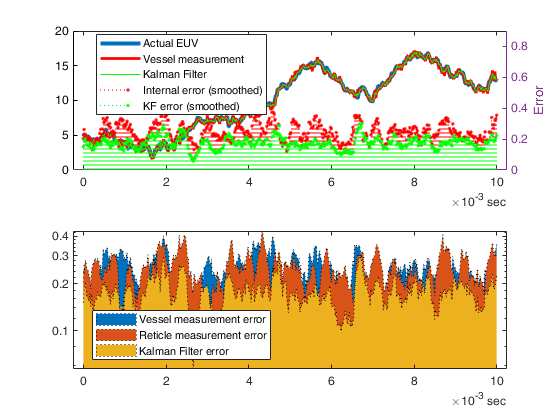

  xkEstimate = xkEstimate+Sk*C'/(C*Sk*C'+Rk)*(yk-C*xkEstimate);
  Hf.EUV_estimate(k) = xkEstimate(1);
  xkEstimate = A*xkEstimate;
  Sk = Sk - Sk*C'/(C*Sk*C' + Rk)*C*Sk;
  Sk = A*Sk*A' + Qk;
  
end
clear h
figure
h(1) = subplot(2,1,1);
plot(Time,Hf.EUV_actual,'linewidth',3)
hold on
plot(Time,Hf.EUV_internal,'r','linewidth',2)
plot(Time,Hf.EUV_estimate,'g')

yyaxis right
stem(Time,movmean(abs(Hf.EUV_internal-Hf.EUV_actual),10),'.:r')
stem(Time,movmean(abs(Hf.EUV_estimate-Hf.EUV_actual),10),'.:g')
ylim(2*ylim)
ylabel("Error")
legend("Actual EUV","Vessel measurement","Kalman Filter","Internal error (smoothed)","KF error (smoothed)",'location','best')
yyaxis left

h(2) = subplot(2,1,2);
opacity = 1;
area(Time,movmean(abs(Hf.EUV_internal-Hf.EUV_actual),10), ...
  "FaceAlpha",opacity, ...
  "LineStyle",":")%,'.-','LineWidth',3)
hold on
opacity = 1;
area(Time,movmean(abs(Hf.EUV_external-Hf.EUV_actual),10),...
  "FaceAlpha",opacity, ...
  "LineStyle",":")%,'.-','linewidth',2)
opacity = 1;

area(Time,movmean(abs(Hf.EUV_estimate-Hf.EUV_actual),10), ...
  "FaceAlpha",opacity, ...
  "LineStyle",":")%,'.-')
ha = gca;
ha.YScale = "log";
legend("Vessel measurement error","Reticle measurement error","Kalman Filter error",'location','best')
linkaxes(h,'x')

I have smoothed the error so that the graphs look more impressive.

Okay, so that's the crash course in Kalman Filtering. You should now have enough background to be able to make use of...

doc kalman

Suggested exercises:

- We've modeled the case where the reticle sensor is 1 shot behind. Try other models, e.g. with extra delay. Also think more broadly about design options at the system level, and how to model these; e.g. suppose you send a raw measurement earlier, which has more noise and possibly a bias, but then you send a corrected measurement later.

- As mentioned, the model for the dynamics of EUV is bad. Try some others.

- We have not added the contribution of the controller. Try adding it (and you might as well use Simulink's Kalman Filter block).

- Note that, in simulation, we have the benefit of knowing the parametrization of the disturbance and noise processes exactly. Think about how to estimate the parametrization when working with real data.

- We have four vessel sensors, so we can at least imagine that separate coefficients for each of those four sensors would be helpful.

- The spectral content of the internal and reticle sensors may be different. Check whether this might be the case (use periodograms, e.g. pwelch).

- (Stretch) Re: #5 -- This can be modeled by using colored noise instead of white noise. This amounts ot building a model for the disturbance and/or noise processes; there's plenty of literature on this.

- (Stretch) Try out some system identification techniques ("help n4sid") to estimate better models of the system.